# Asesoria

### Metodos Numericos

#### 2022-2S : 12/09/2022

Particular example, use of symbolics

### Quantum Mechanics

*Expected values and standard deviation for position of a particle in an infinite square potential*

clear
syms psi(x)
syms x n L h real 

psi(x) = sqrt(2 / L) * sin(pi * x / L)

$$psi(x) = \sqrt{2}\,\sin\left(\frac{\pi \,x}{L}\right)\,\sqrt{\frac{1}{L}}$$

diff(psi, x), diff(psi, x, 2)

$$ans(x) = \frac{\pi \,\sqrt{2}\,\cos\left(\frac{\pi \,x}{L}\right)\,\sqrt{\frac{1}{L}}}{L}$$

$$ans(x) = -\frac{\sqrt{2}\,\pi^{2}\,\sin\left(\frac{\pi \,x}{L}\right)\,\sqrt{\frac{1}{L}}}{L^{2}}$$

xbar = simplify(int(psi * - i * h* diff(psi, x), [0, L]))

$$xbar = 0$$

x2bar = simplify(int(psi * (- i * h)^2* diff(psi, x, 2), [0, L]))

$$x2bar = \frac{h^{2}\,\pi^{2}}{L^{2}}$$

nx2barexpr = (h^2*sym(pi)^2) * n^2/L^2

$$nx2barexpr = \frac{h^{2}\,n^{2}\,\pi^{2}}{L^{2}}$$

sigmax = simplify(sqrt(x2bar - xbar^2))

$$sigmax = \frac{\pi \,\left|h\right|}{\left|L\right|}$$

nsigmaexpr = simplify(sqrt(nx2barexpr - xbar^2))

$$nsigmaexpr = \frac{\pi \,\left|h\right|\,\left|n\right|}{\left|L\right|}$$

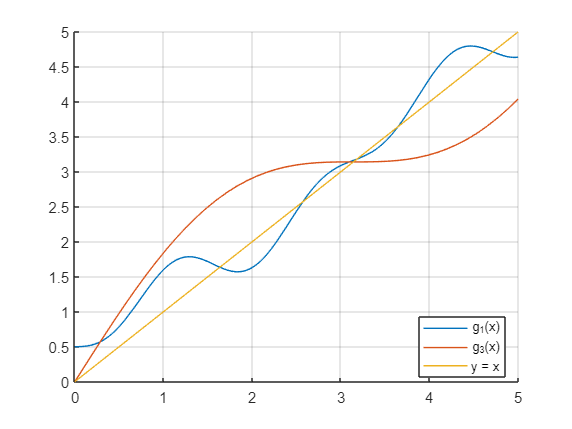

format long
syms g(x) [1 3]

g1(x) = x + 1/ 2 * (exp(-x) - sin(x)*cos(3*x));

g3(x) = x + sin(x);

clf('reset')
hold on
fplot(g1, [0 5], 'DisplayName', 'g_1(x)')
fplot(g3, [0 5], 'DisplayName', 'g_3(x)')
fplot(x, [0 5], 'DisplayName', 'y = x')
grid on
legend('Location','best')
hold off

g3 = matlabFunction(g3);
c = fixpt(g3, 3, 1e-15, 100)

c =    3.141592653589793


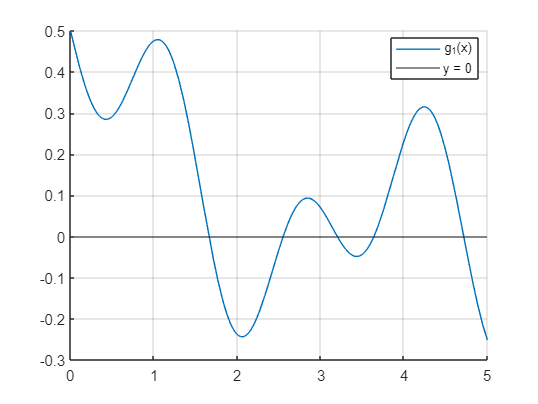

clear
syms g(x) [1 3]

g1(x) = 1/ 2 * (exp(-x) - .7*sin(x)*cos(3*x));

clf('reset')
hold on
fplot(g1, [0 5], 'DisplayName', 'g_1(x)')
yline(0, 'DisplayName', 'y = 0')
grid on
legend('Location','best')
hold off

clear

f = @(x) sin(x);
X = linspace(0, 7, 5)

X =          0    1.7500    3.5000    5.2500    7.0000


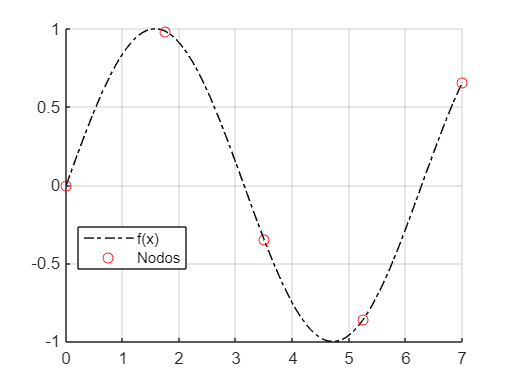

Y = f(X);

clf('reset')
hold on
fplot(f, [0 7], '-.k','DisplayName', 'f(x)')
plot(X, Y, 'or','DisplayName', 'Nodos')
grid on
legend('Location','best')
hold off

[P, L] = lagran(X, Y)

P =    -0.0087    0.1887   -1.1836    2.1022         0


L =     0.0044   -0.0777    0.4762   -1.1905    1.0000
   -0.0178    0.2799   -1.4150    2.2857         0
    0.0267   -0.3732    1.5510   -1.7143         0
   -0.0178    0.2177   -0.7619    0.7619         0
    0.0044   -0.0466    0.1497   -0.1429         0


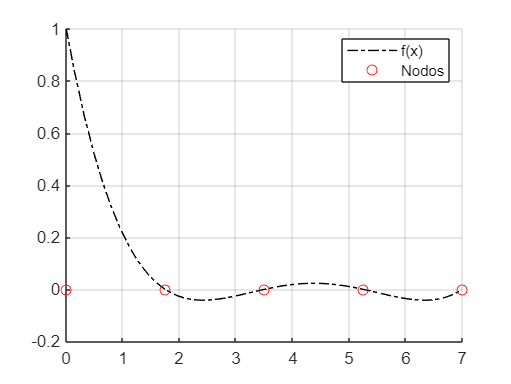

L1 = @(x) polyval(L(1, :), x); % Polinomio asociado a la primera fila

clf('reset')
hold on
fplot(L1, [0 7], '-.k','DisplayName', 'f(x)')
plot(X, zeros(size(X)), 'or','DisplayName', 'Nodos')
grid on
legend('Location','best')
hold off

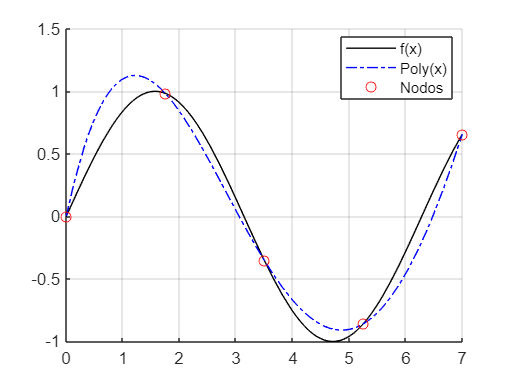

Poly = @(x) polyval(P, x);
clf('reset')
hold on
fplot(f, [0 7], 'k','DisplayName', 'f(x)')
fplot(Poly, [0 7], '-.b','DisplayName', 'Poly(x)')
plot(X, Y, 'or','DisplayName', 'Nodos')
grid on
legend('Location','best')
hold off

[P, D] = newpoly(X, Y)

P =    -0.0087    0.1887   -1.1836    2.1022         0


D =          0         0         0         0         0
    0.9840    0.5623         0         0         0
   -0.3508   -0.7627   -0.3786         0         0
   -0.8589   -0.2904    0.1350    0.0978         0
    0.6570    0.8662    0.3305    0.0372   -0.0087


Aumentada = [X' D]

Aumentada =          0         0         0         0         0         0
    1.7500    0.9840    0.5623         0         0         0
    3.5000   -0.3508   -0.7627   -0.3786         0         0
    5.2500   -0.8589   -0.2904    0.1350    0.0978         0
    7.0000    0.6570    0.8662    0.3305    0.0372   -0.0087


Diferencia = (-.8589 - -.3508) / (5.25 - 3.5)

Diferencia = -0.2903

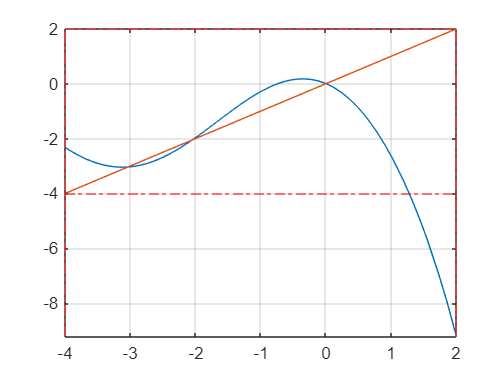

format long
clear
syms f(x)

f(x)= 2*cos(x)-exp(x)-1;
df(x) = diff(f, x);
d2f(x) = diff(df, x);

a=-4;
b=2;
fplot(f,[a,b]);
grid on
hold on
fplot(x,[a,b]); %Verificar punto fijo
yline(a, '-.r');%Para verificar si cumple teorema debe estar acotada entre esta y la de abajo
yline(b, '-.r'); %VARIAR A,B EN BASE A OPCIONES
xline(a, '-.r');
xline(b, '-.r');
hold off

f = matlabFunction(f);
[p, k, err, P] = fixpt (f, -3, 1e-5, 100)

p =   -3.037053214961455


k =      6


err =      2.672735972941709e-05


P =   -3.029772061568755
  -3.035835830987551
  -3.036860412388547
  -3.037026487601726
  -3.037053214961455


eval(df(-3)), eval(df(-2)), eval(df(0))

ans =    0.232452947751870


ans =    1.683259570414751


ans =     -1


[p, k, err, P] = fixpt (f, 1e-2, 1e-5, 1e7)

maximum number of iterations exceeded


p =      1.548829456767820e-04


k =     10000001


err =      3.098018905529631e-04


P =   -0.010150166250837
   0.009995802169908
  -0.010145842303170
   0.009991609637159
  -0.010141523864936
   0.009987422390608
  -0.010137210924455
   0.009983240419140
  -0.010132903470081
   0.009979063711676


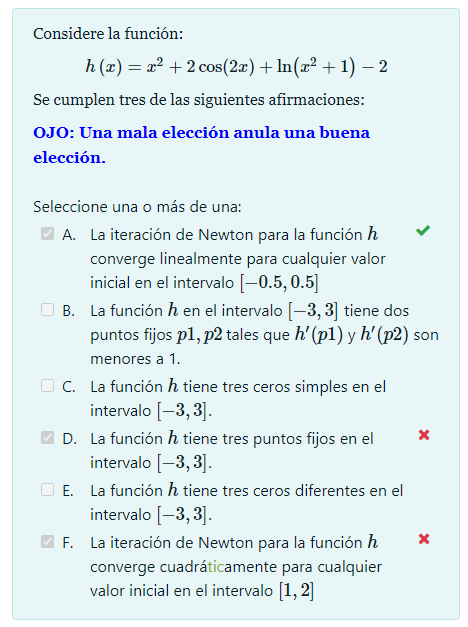

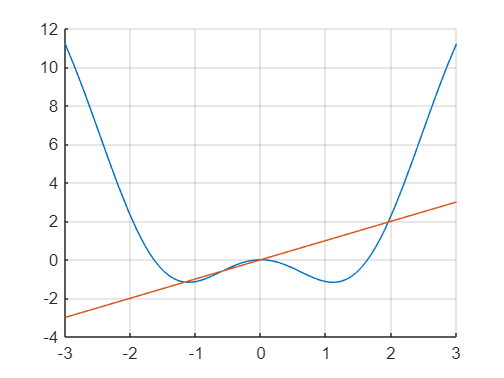

clear
syms h(x)

h(x) = x^2 + 2* cos(2*x) + log(x^2 + 1) - 2;

clf('reset')
hold on
fplot(h(x),[-3, 3]);
fplot(x, [-3, 3])
grid on
hold off

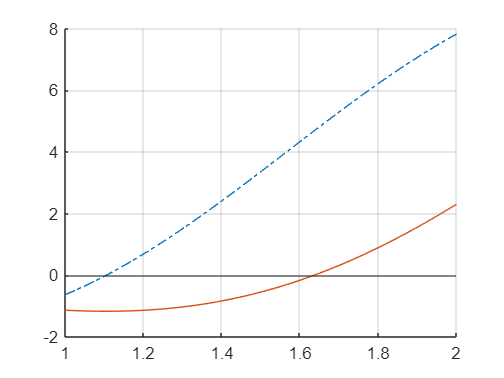

df(x) = diff(h, x);
clf('reset')
hold on
fplot(df,[1, 2], '-.')
fplot(h(x),[1, 2]);
yline(0)
grid on
hold off